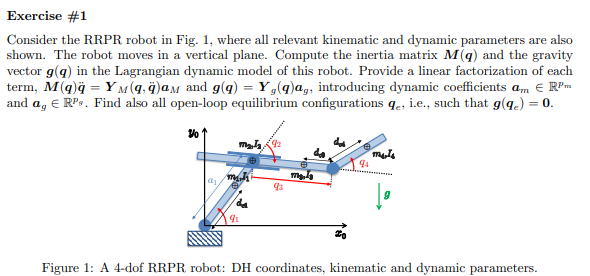

% clear all, clc, close all
% % This part is isolated from previous sectionclear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% % 1:revolute; 0:prismatic
% sigma = [1,1,0,1];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% 
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% % g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% % g=[0,-g0*sin(alpha_angle),0]';
% [Rx,Ry,Rz]=getEulerRotationMatrices([-alpha_angle,0,0])
% % g=[0,-g0*sin(alpha_angle),-g0*sin(alpha_angle)]'
% g=[0,-g0,0]'
% % g=vpa(expand(Rx*g))
% R2Robot=['rrpr';'xxxx';sigma]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% 
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};!! pay attention to this
% % z.rcdefined=true;

% %% the following assumptions are due to the inexistence of l1 and dc1   
% % dc(2)=0
% % l(2)=0
% z.dc=dc;
% z.l=l;
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % % l(1)=0 %don't do this because dc1 is going to dissaperar
% z.opt_expr={[l(2),dc(2)],[0,0]};%use this instead

% 
% z.prismatic_CoM_method(3)=2;
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z);
% w
% vc
% T
% Ti
% M
% [C,cac,Csubs,S] = getCs(M,q,q_dot);
% cac

% vc(:,3)

% % qd
% 

% 
% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor);
% g_q_short
% U{:}

% %[All, dynamicParamsReturn, a]= getDynamicParameters([M,(S),diag(g_q)],q,[g],2)
% % [All, dynamicParamsReturn, a]= getDynamicParameters2([M,diag(g_q)],q,[l;g0]',2)

% 
% % [Msubs, dynamicParamsReturn, a]=getDynamicParameters2(M,q,l',2)%l')
% 

% [Msubs, dynamicParamsReturnM, aM]=getDynamicParameters3(M,q,[l],2)

% 
% [gsubs, dynamicParamsReturng, ag]=getDynamicParameters3(g_q,q,[g0],2)

% 
% Msubs
% dynamicParamsReturnM
% gsubs
% dynamicParamsReturng
% % M

% % Msubs = All(:,1:4)
% % Ssubs = All(:,4:6)
% % gSubs = diag(All(:,5:8))
% % FSubs = All(:,10:12)

% % torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd
% a_orderM=aM([1,4,5,3,6,2])

% [YM,YM_short]=getLinearParametrization(Msubs*q_ddot,a_orderM)

% % torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd
% a_orderg=ag([2,3,1,4])

% [Yg,Yg_short]=getLinearParametrization(gsubs,a_orderg)

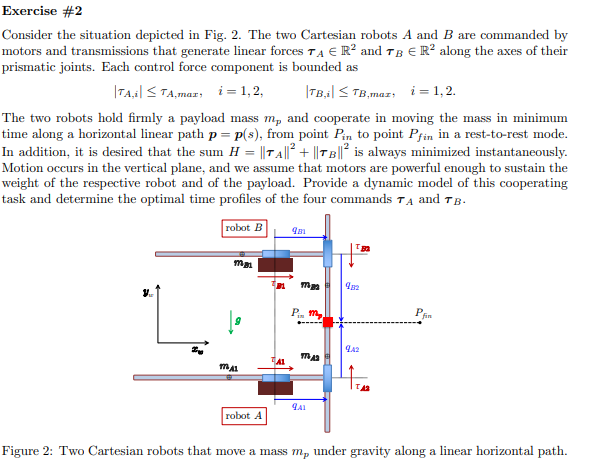

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma_mp = [1,1]; %% rot=0 prismatic=1
% n_mp = length(sigma_mp);
% % t = sym('t', 'real');
% 
% q_d= sym('q_d', [n_mp 1],'real');
% 
% 
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% 
% R2Robot=['pp';'yx';[sigma_mp]]    
% 
% z_mp = Gen_param(n_mp);
% z_mp.g=[0,-g0,0]';
% z_mp.sigmaD=R2Robot;
% z_mp.l=sym('l', [n_mp 1],'real');
% z_mp.q=sym('q', [n_mp 1],'real');
% z_mp.q_dot=sym('q_dot_', [n_mp 1],'real');
% z_mp.q_ddot = sym('q_ddot_', [n_mp 1],'real');
% z_mp.dc=sym('dc', [n_mp 1],'real');
% z_mp.m=sym('m_p', [n_mp 1],'real');
% z_mp.I=sym('I', [n_mp 1],'real');
% z_mp.methodD=1;
% % z.dhTable=[]
% z_mp.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z_mp.angle_=sym(zeros(1,n_mp));
% 
% z.opt_expr={[z_mp.m(1)],[0]};
% z_mp.m(1)=0
% % z.rcdefined=true;

% [Pc_mp,vc_mp,w_mp,T_mp,Ti_mp,M_mp] = getGenericPC2(z_mp)
% [C_mp,cac_mp,Csubs_mp,S_mp] = getCs(M_mp,z_mp.q,z_mp.q_dot)

% isMotor_mp=false
% [g_q_mp, PE_mp, U_mp,g_q_short_mp,PE_short_mp] = getGravityWithPc(Pc_mp, z_mp.q, z_mp.l, z_mp.m, z_mp.dc, z_mp.g, isMotor_mp)

% M_mp
% Pc_mp
% g_q_mp

%  u_subs_mp = M_mp*z_mp.q_ddot +S_mp*z_mp.q+g_q_mp

% 
% % This part is isolated from previous section
% % clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0]; %% rot=0 prismatic=1
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% % m(2)=m(2)+m_p;
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% 
% R2Robot=['pp';'xy';[1,1]]    
% 
% z = Gen_param(n);
% z.g=[0,-g0,0]';
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot = q_ddot ;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% %  z.opt_expr={[l(1),dc(1)],[0,0]};
% % z.rcdefined=true;

% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, z.g, isMotor)

% M
% Pc
% g_q

%  u_subs = M*z.q_ddot +S*z.q+g_q
 

## Continued by hand

## defining function trajectory

% z_path_params.func_name="xy_line"; %moves in the y axis
% z_path_params.replacevars=true;
% z_path_params.dir=1;%1 up, 0 going down
% z_path_params.v_=[1,1]';
% z_path_params.enabled_axis=[1,0]'%to show if weneed a x lline or in y or in x and y, [1,0]' [0,1]' [1,1]'
% % z_path_params.P_=[sym('P_x_0','real'),sym('P_y_0','real')];
% 
% xyonly_=true
% z_path = common_trajectory_func(z_path_params,xyonly_);

% z_path.rd
% z_path.rd_t
% z_path.rd_t_dot
% z_path.rd_t_ddot
% if(z_path_params.replacevars)
%     z_path.rd_
%     z_path.rd_dot_
%     z_path.rd_ddot_
%     
%     z_path.rd_t_
%     z_path.rd_t_dot_
%     z_path.rd_t_ddot_
%     
% end
%  
%  

## 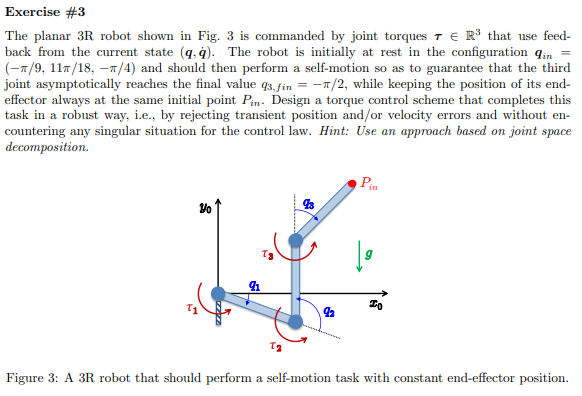

clear all, clc, close all
% This part is isolated from previous sectionclear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,1,1];
R2Robot=['rrr';'xxx';sigma]    

R2Robot = 3×3 char array
    'rrr'
    'xxx'
    ''


n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');

m_p = sym('m_p','real');
d = sym('d','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
% g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% g=[0,-g0*sin(alpha_angle),0]';


z = Gen_param(n);
z.g=[0,-g0,0]';
z.sigmaD=R2Robot;

z.q=q;
z.q_dot=q_dot;
z.q_ddot =q_ddot;
z.dc=dc;

z.I=I;
z.methodD=1%with DH tablemethod=2, other case method=1

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: []
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: []
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismoto

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.l=l;
z.m=m;
% z.opt_expr={[l(1),dc'],[0,0,d]};
% z.rcdefined=true;
% z.prismatic_CoM_method=[1,2];1%% normal mode onle CoM=dc(i) in %% 2 inverse mdoe CoM=q(i)-dc(i) %% for the moment only for prismatics

## computing M

[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

[C,cac,Csubs,S] = getCs(M,q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, z.g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccccccccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{3}\right) & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$

$$PE\_short = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$

$$g\_q\_short = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$g\_q = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$

U = 1×3 cell array
    {[dc1*g0*m1*sin(q_1)]}    {[g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))]}    {[g0*m3*(l2*sin(q_1 + q_2) + l1*sin(q_1) + dc3*sin(q_1 + q_2 + q_3))]}


$$g\_q\_short = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$PE\_short = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+{\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$


% T
% Ti(:)
Trans.PTotal

$$ans = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 \end{array}\right)$$

Trans.Jacobian_PTotal

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{1} & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{2} & l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

Pc

$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

M

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)+2\,l_{1}\,l_{2}\,m_{3}\,\cos\left(q_{2}\right) & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+m_{3}\,{l_{2}}^{2}+l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

S

$$S = \begin{array}{l} \left(\begin{array}{ccc} -l_{1}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\sigma_{2}-{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\sin\left(q_{2}+q_{3}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)-\sigma_{1} & -l_{1}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\,\sigma_{2}-{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\sin\left(q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)-\sigma_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,\left(l_{1}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{3}\right)\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)\\ l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)\,\sigma_{2}+\sigma_{4}-\sigma_{1} & -\sigma_{1} & -{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)\\ \sigma_{4}+\sigma_{3} & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{2}={\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\\ \sigma_{3}={\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ \sigma_{4}={\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,{\dot{q}}_{1}\,\sin\left(q_{2}+q_{3}\right) \end{array}$$

g_q

$$g\_q = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}\right)+\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

% cac
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
tau =simplify( M*z.q_ddot + cac+g_q);
% 
tau

% tau_=subs(tau)

% C{:}
% R=sym('R','real')
% vars2replace =[q(2);q_dot(1)]
% vars2replace_=[R;0]
% tau_=subs(tau,vars2replace,vars2replace_)

## computing maximun aceleration

clear all;
close all;
clc;
m_=10

m_ = 10

l_=2

l_ = 2

theta_T=pi;
theta_s_=theta_T/6

theta_s_ = 0.5236

I_=m_*l_^2/12

I_ = 3.3333

g_0=9.81

g_0 = 9.8100

d_=l_/2

d_ = 1

tau_g_max_=m_*g_0*d_

tau_g_max_ = 98.1000

tau_max_=200

tau_max_ = 200

sin(theta_s_)

ans = 0.5000

T_min=sqrt(16*I_*pi/(3*(tau_max_-tau_g_max_*sin(theta_s_))))

T_min = 0.6083

## bang cost bang profile

T=sym('T','real');
V1=sym('V1','real');
A1=sym('A1','real');
T_=1*T_min%1.2165;

T_ = 0.6083

% T_=1.2165;
Ts_=T_/4

Ts_ = 0.1521

A1_=16*pi/(3*T_^2);
Ts=T/4;
V1=Ts*A1;
V1_=Ts_*A1_;
qA=[0,1]'

qA =      0
     1


qB_=[pi,pi]'

qB_ =     3.1416
    3.1416


qB=sym('qB',[2,1],'real');

I_0=1

I_0 = 1

% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
[qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)

$$qa\_piece1 = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ 0 & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ A_{1}\,\mathrm{Ts} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ A_{1}\,\mathrm{Ts}-A_{1}\,\left(\mathrm{Ts}-T+t\right) & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ -\frac{A_{1}\,\mathrm{Ts}\,\left(\mathrm{Ts}-2\,t\right)}{2} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,\mathrm{Ts}-2\,T\,t+2\,{\mathrm{Ts}}^{2}+t^{2}\right)}{2} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ 0 & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ V_{1} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ A_{1}\,\left(T-t\right) & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ \frac{V_{1}\,\left(2\,t-\frac{V_{1}}{A_{1}}\right)}{2} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,t+\frac{2\,{V_{1}}^{2}}{{A_{1}}^{2}}+t^{2}-\frac{2\,T\,V_{1}}{A_{1}}\right)}{2} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{V_{1}+A_{1}\,t}{A_{1}} \end{array}$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 45.29 & \text{ if }t\in \left[0.0,0.1521\right)\\ 0.0 & \text{ if }t\in \left[0.1521,0.4562\right)\\ -45.29 & \text{ if }t\in \left[0.4562,0.6083\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 45.29\,t & \text{ if }t\in \left[0.0,0.1521\right)\\ 6.886 & \text{ if }t\in \left[0.1521,0.4562\right)\\ 27.55-45.29\,t & \text{ if }t\in \left[0.4562,0.6083\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 22.64\,t^{2} & \text{ if }t\in \left[0.0,0.1521\right)\\ 6.886\,t-0.5236 & \text{ if }t\in \left[0.1521,0.4562\right)\\ -22.64\,t^{2}+27.55\,t-5.236 & \text{ if }t\in \left[0.4562,0.6083\right] \end{array}\right. \end{array}\right)$$

T_ = 0.6083

Ts_ = 0.1521

$$t = t$$

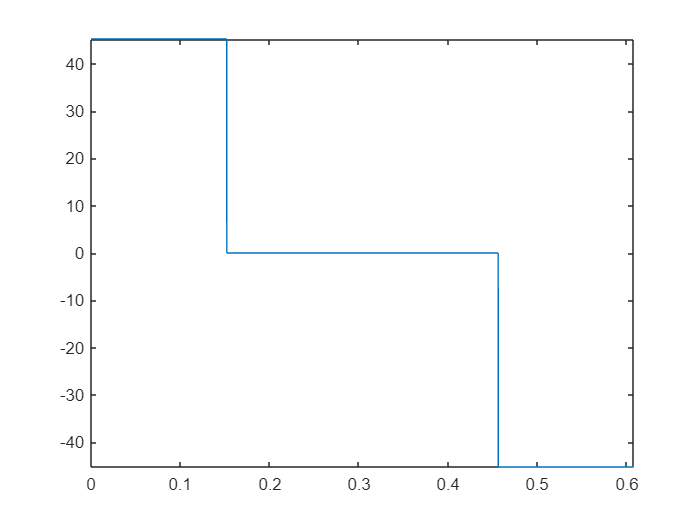

fplot(qa_piece2(1,:),[0,T_])

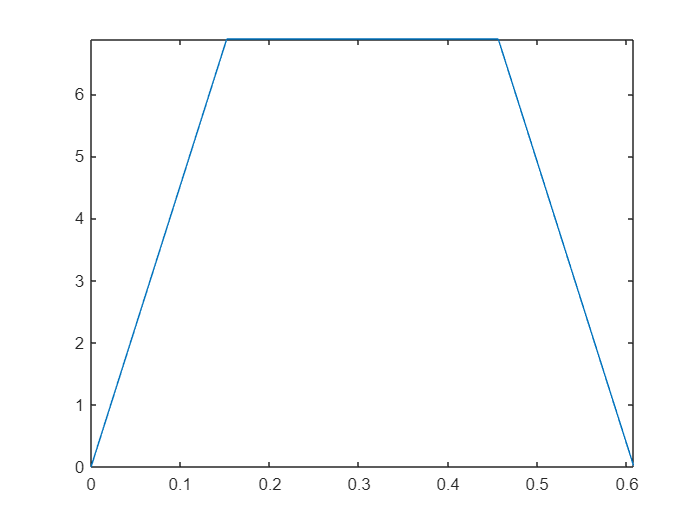

figure
fplot(qa_piece2(2,:),[0,T_])

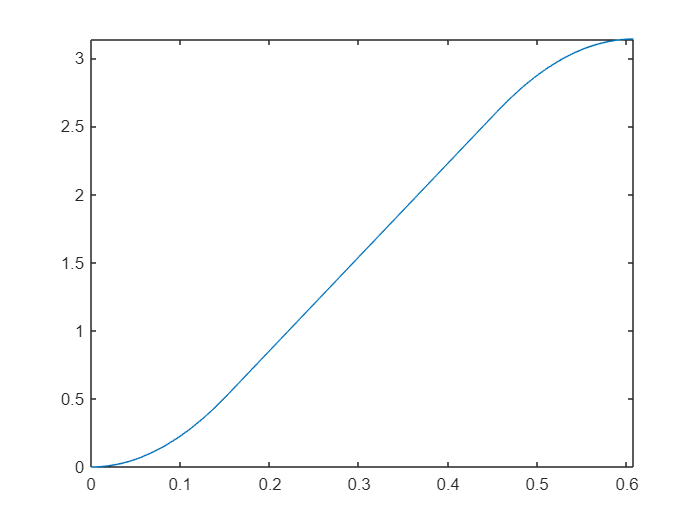

figure
fplot(qa_piece2(3,:),[0,T_])

figure
% [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% tau_2=int(qa_piece2,t)

## tau 2

tau_func=I_*qa_piece2(1,:)+tau_g_max_*sin(qa_piece2(3,:))

$$tau\_func = \left\{ \begin{array}{cl} \frac{981\,\sin\left(22.642500000016298145055770874023\,t^{2}\right)}{10}+150.95000000010865430037180582682 & \text{ if }t\in \left[0.0,0.15206775097840363741852343082428\right)\\ \frac{981\,\sin\left(6.8863881030556512996554374694824\,t-0.52359877559865708462893962860107\right)}{10} & \text{ if }t\in \left[0.15206775097840363741852343082428,0.4562032529356656596064567565918\right)\\ -\frac{981\,\sin\left(22.642500000016298145055770874023\,t^{2}-27.54555241222260519862174987793\,t+5.2359877559792948886752128601074\right)}{10}-150.95000000010865430037180582682 & \text{ if }t\in \left[0.4562032529356656596064567565918,0.60827100391361454967409372329712\right] \end{array}\right.$$

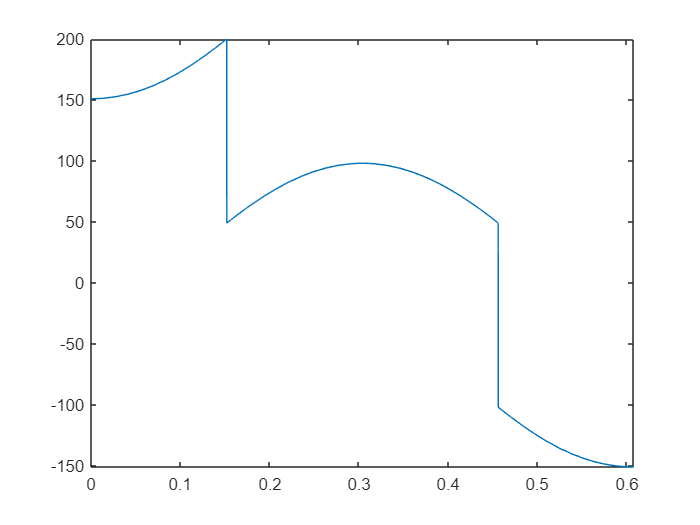

fplot(tau_func,[0,T_])

% figure
% fplot(qa_piece2(2,:),[0,T_])
% figure
% fplot(qa_piece2(3,:),[0,T_])

Exercise 4

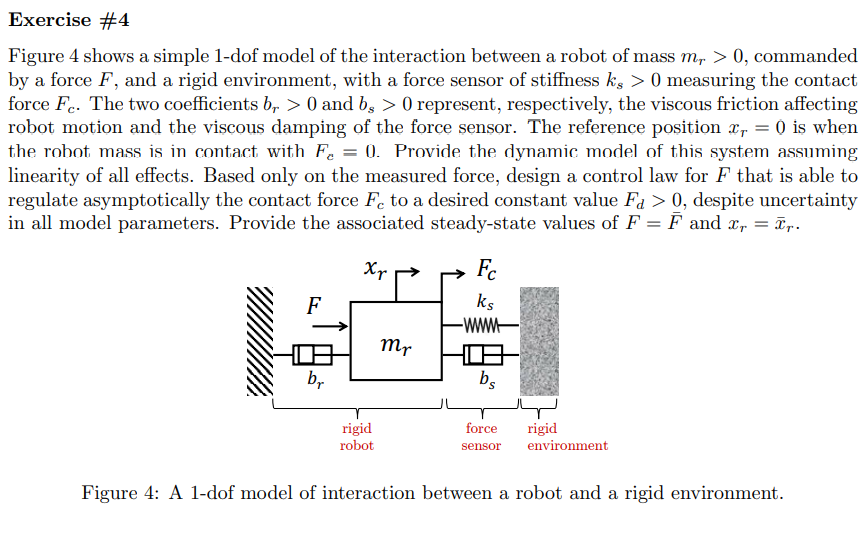

% % % This part is isolated from previous section
clear;clc
% %
% % % syms k q1(t) q2(t) q3(t)
sigma = [1];
R2Robot=['s';'x';sigma];
n = length(sigma);
t = sym('t', 'real');

x_r=sym('x_r','real');
x_r_dot=sym('x_dot_r','real');
x_r_ddot=sym('x_ddot_r','real');

x_w=sym('x_w','real');
x_w_dot=sym('x_dot_w','real');
x_w_ddot=sym('x_ddot_w','real');

m_r=sym('m_r','real');
m_w=sym('m_w','real');

F_c=sym('F_c','real');
F_w=0*sym('F_w','real');


b_r=sym('b_r','real');
b_s=sym('b_s','real');
b_w=sym('b_w','real');

k_r=0*sym('k_r','real');
k_s=sym('k_s','real');
k_w=sym('k_w','real');

q = sym('q_', [n 1],'real');
q_derivated=derivate_D(q,n,t,'q');
qd = q_derivated.dot;
qdd = q_derivated.ddot;

z = Gen_param(n);

z.sigmaD=R2Robot;
% z.q=q;
% z.q_dot=qd;
% z.q_ddot=qdd;

z.q=[x_r]';
z.q_dot=[x_r_dot]';
z.q_ddot=[x_r_ddot]';
z.k=[k_r,k_s]' ;
z.b=[b_r,b_s]' ;
z.m_spring=[m_r]' ;
z.F=[F_c]' ;


[spring_models,F_springs_,z]=Spring_model(z);

% F_spring_(1,1)=spring_models(1).F_;
% F_spring_(2,1)=spring_models(2).F_;
% F_spring_=collect(expand(F_spring_),[z.k;z.b])

F_spring_=collect(expand(F_springs_),[z.k;z.b])

$$F\_spring\_ = x_{r}\,k_{s}+{\dot{x}}_{r}\,b_{r}+{\dot{x}}_{r}\,b_{s}+m_{r}\,{\ddot{x}}_{r}$$

expand(sum(F_spring_))

$$ans = b_{r}\,{\dot{x}}_{r}+b_{s}\,{\dot{x}}_{r}+k_{s}\,x_{r}+m_{r}\,{\ddot{x}}_{r}$$